# [IPSA] - Automatique - Projet drone

# Fichier de paramètres - perturbations

Auteur : Adrien Jacob 

Afin de se rapprocher au plus près du système réel, nous allons modéliser :

- Des perturbations sur le signal de commande *(défauts moteurs, jeux mécaniques)*

- Des perturbations sur le signal de retour* (bruits capteurs)*

- Des perturbations sur les états du système *(phénomènes exogènes comme le vent, etc...)*

______________________________________________________________________________________________________________

## 1. Modèle de perturbation : bruit blanc filtré

*=> cf. TD 03 et cours 08 pour le modèle de perturbation utilisé*

Simulink permet de créer son propre bloc custom pour une interface utilisateur simplifiée.

Le bloc "perturbation" dans le `Simulink_template` a été créé dans ce sens : 

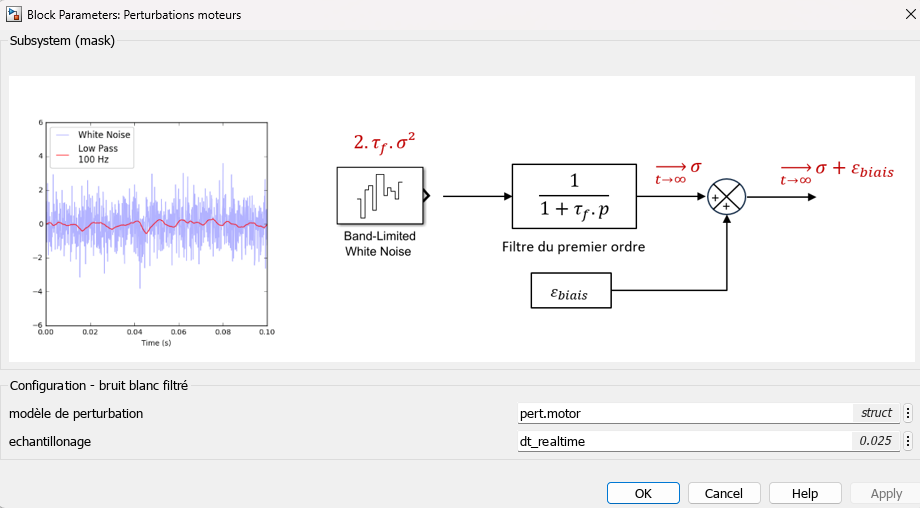

Dans le mask *(look under mask)*

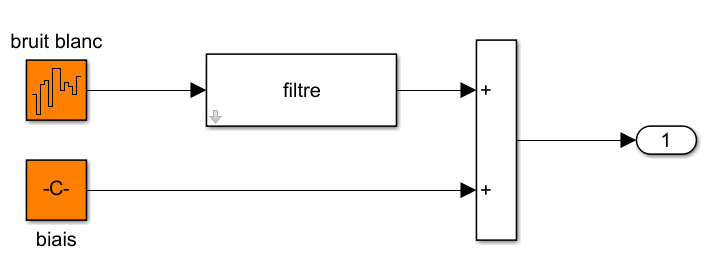

______________________________________________________________________________________________________________

## 2. Implémentation 

*=> cf. cours 08 *

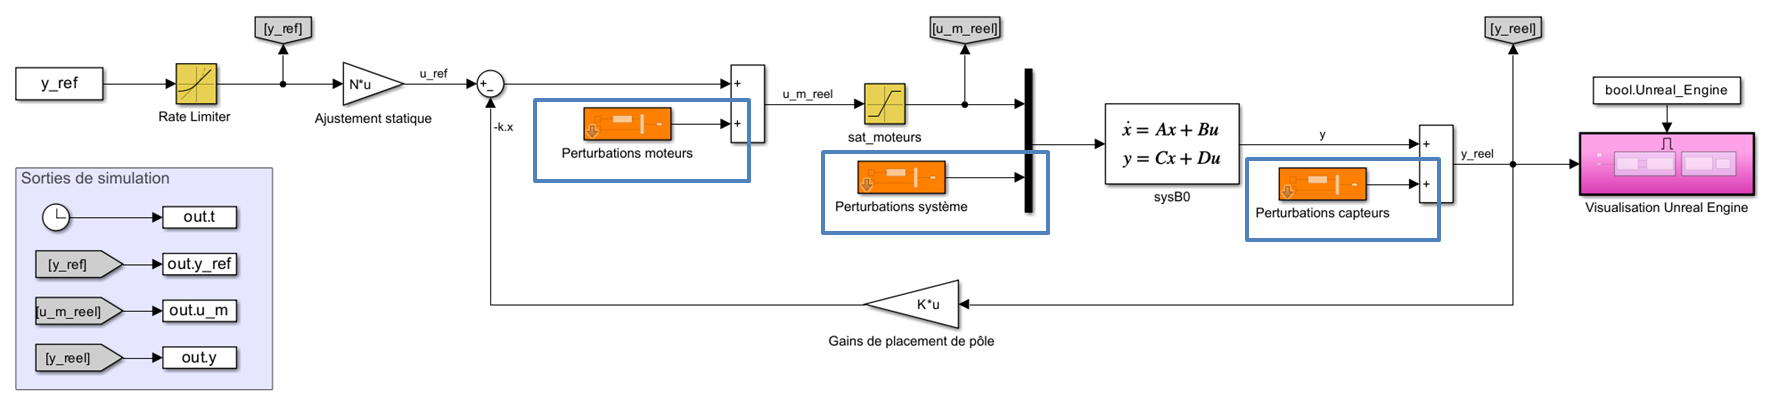

______________________________________________________________________________________________________________

## 3. Paramètres des perturbations

### 3.1. La perturbation en entrée (moteur)

Notre entrée moteur correspond au $\omega ²$ de rotation des hélices.

Première approximation pour ce type de moteur :

**P.S. **Prenons un sigma du même ordre de grandeur mais qui ne dépend pas des moteurs

tau = 1 / (2*pi*10);
sigma = 0.01 * 1e5 .* [1 , 1 , 1 , 1];

pert.motor.noise_power = 2*tau*sigma.^2;
pert.motor.filtre = blkdiag(...
    tf( 1 , [tau 1]), ...
    tf( 1 , [tau 1]), ...
    tf( 1 , [tau 1]), ...
    tf( 1 , [tau 1]));

pert.motor.biais = [0 , 0 , 0 , 0];
pert.motor.seed = randi([1 1000],1,4);

### 3.2. La perturbation en sortie (capteur)

Notre sortie capteur correspond à l'ensemble des états.

Première approximation pour ce type de capteurs :

tau = 1 ./ (2*pi .* [1 , 1 , 1 , 1 , 1 , 1 , 10 , 10 , 10 , 10 , 1 , 10]);
sigma = [1e-2 , 1e-3 , 1e-2 , 1e-3 , 1e-2 , 1e-3 , 1e-3 , 1e-4 , 1e-3 , 1e-4 , 1e-3 , 1e-4];

pert.capteur.noise_power = 2*tau .* sigma.^2;
pert.capteur.filtre = blkdiag( ...
    tf(1, [tau(1)  1]), ...
    tf(1, [tau(2)  1]), ...
    tf(1, [tau(3)  1]), ...
    tf(1, [tau(4)  1]), ...
    tf(1, [tau(5)  1]), ...
    tf(1, [tau(6)  1]), ...
    tf(1, [tau(7)  1]), ...
    tf(1, [tau(8)  1]), ...
    tf(1, [tau(9)  1]), ...
    tf(1, [tau(10) 1]), ...
    tf(1, [tau(11) 1]), ...
    tf(1, [tau(12) 1]) );

pert.capteur.biais = [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0];
pert.capteur.seed = randi([1 1000],1,12);

### 3.3. La perturbation sur le système (vent)

**/!\ Attention**, cette perturbation est interne au système et subit sa dynamique.

Première approximation pour ce type de perturbations :

**P.S. **On ajoute un biais constant de vent

tau = 1 / (2*pi*2);
sigma = [0.5, 0.5, 0.25, 0.1, 0.1, 0.1];

pert.vent.noise_power = 2*tau*sigma.^2;
pert.vent.filtre = tf( 1 , [tau 1]) .* eye(6);
pert.vent.biais = [2 , 2 , 1 , 0 , 0, 0];
 
pert.vent.seed = randi([1 1000],1,6);

### 4. Clear workspace

clear tau sigma;